# Final Modelado & Optimización II

## Ejercicio #1

Primero obtenemos los datos de las funciones para encontrar los parámetros de nuestras funciones S(t) y U(t)

Insertamos los valores de las funciones evaluadas en dos puntos y esos dos puntos. El programa realiza el despeje para las constantes de las funciones. 

b = 0.75
a = 12000

c = 4000000
d = 0.7

Creamos las funciones con las constantes anteriormente obtenidas. 

syms t
funS = @(t) c*exp(-d*t);
funC = @(t) a*exp(b*t);

K = funS(0)

Linea auxiliar debido a que la función G de costos incluye una integral, por ello debemos obtener el resultado simbólico de la integral y convertirlo a función del tiempo

funCintegrada = matlabFunction(int(funC,0,t))

Creamos la función G(t) y la graficamos en un intervalo limitado

G = @(t) K/t + 1/t*funCintegrada(t) -funS(t)/t
fplot(G)
axis([0 20 0 3e7])

Observamos que el mínimo sucede alrrededor del cinco, debemos dar esto como parámetros a nuestro método Newton Rhapson junto con la función G para encontrar el mínimo. 

La función genera el tiempo óptimo así como el valor de la función objetivo en ese punto. 

[tOpt, fObj] = newtonRaphsonMinimo(G, 5)

## Ejercicio 2

### Inciso a-b

syms t G
C1 = 80;
C2 = 5;

F = @(t) 1-2*exp(-t)+exp(-2*t);
R = @(t) 1- F(t);
interR = matlabFunction(int(R, 0, t));

CER(t) = C1*F(t)+C2*R(t);
TEO(t) = interR(t);
G1 = @(t) (C1*F(t)+C2*R(t))/interR(t)

G1 = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/interR(t)


fplot(G1)

axis([0.01 0.5 0 1000])
%grid on
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3);
RES2B1 = tOpt

RES2B1 = 0.3477

RES2B2 = double(CER(tOpt))

RES2B2 = 11.4684

RES2B3 = double(TEO(tOpt))

RES2B3 = 0.3368

RES2B4 = double(G1(tOpt))

RES2B4 = 34.0512

### Inciso C

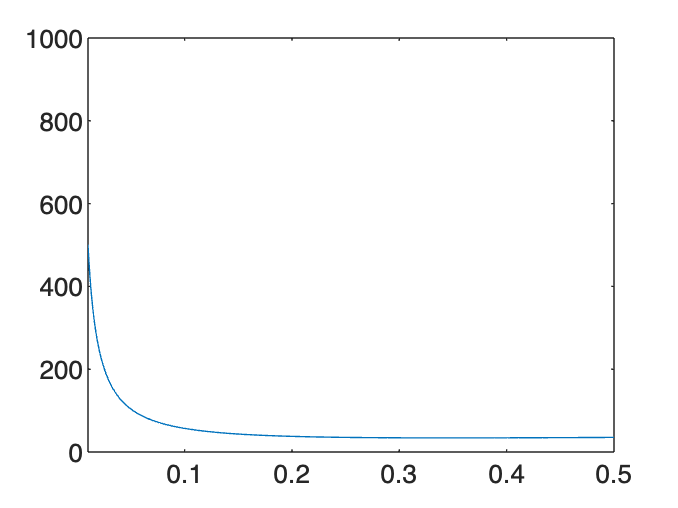

hold off

U =  G*interR(t)-C1*F(t)-C2*R(t)

$$U = 150\,{\mathrm{e}}^{-t}-75\,{\mathrm{e}}^{-2\,t}+G\,\left(\frac{{\mathrm{e}}^{-2\,t}}{2}-2\,{\mathrm{e}}^{-t}+\frac{3}{2}\right)-80$$

Udf = diff(U,t)

$$Udf = 150\,{\mathrm{e}}^{-2\,t}-150\,{\mathrm{e}}^{-t}+G\,\left(2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}\right)$$

Udf = matlabFunction(Udf, 'Vars', {t,G});
Udf = @(G) Udf(tOpt,G);
fplot(Udf, [0,100]);hold on;fplot(@(t) 0, [0,100]);title("Plot dfU(t,k)/dt con t=tOpt vs G");xlabel("G");hold off;grid on

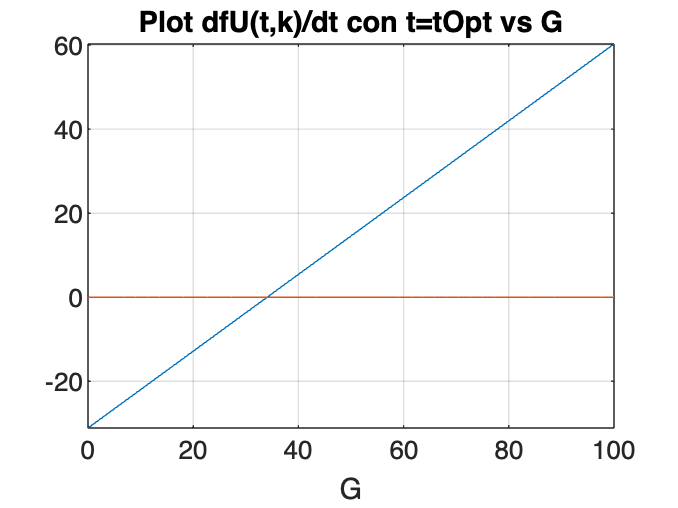

hold off

root = fzero(Udf, 2)

root = 34.0512

U = @(t) root*interR(t)-C1*F(t)-C2*R(t)

U = function_handle with value:
    @(t)root*interR(t)-C1*F(t)-C2*R(t)


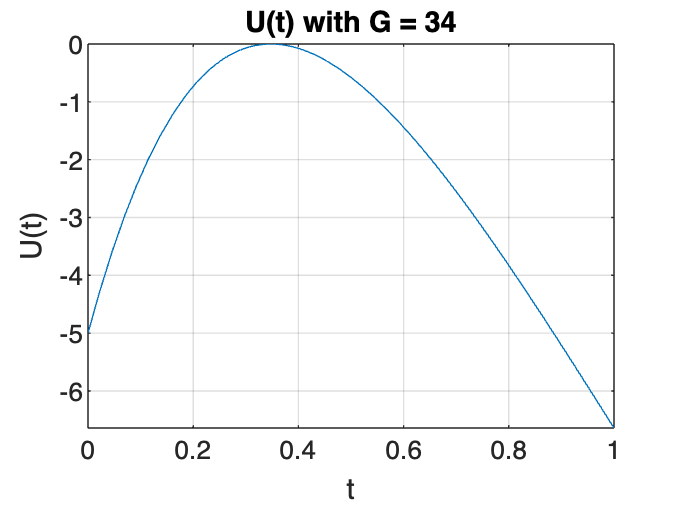

fplot(U, [0,1]);title("U(t) with G = 34");xlabel("t");ylabel("U(t)");grid on

[tOpt2, fObj2] = newtonRaphsonMinimo(U, .3)

tOpt2 = 0.3477

fObj2 = -2.6645e-15

## Problema 3

### Inciso c) Enfoque Tradicional

syms t
C1 = 5;
C2 = 1;

a = 0;
b = 20;

f = @(t) 1/(b-a)

f = function_handle with value:
    @(t)1/(b-a)


F = matlabFunction(int(f, 0, t))

F = function_handle with value:
    @(t)t./2.0e+1


R = @(t) 1- F(t)

R = function_handle with value:
    @(t)1-F(t)


interR = matlabFunction(int(R, 0, t))

interR = function_handle with value:
    @(t)t.*(t-4.0e+1).*(-1.0./4.0e+1)



G = @(t) (C1*F(t)+C2*R(t))/interR(t)

G = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/interR(t)


fplot(G,[4,18])

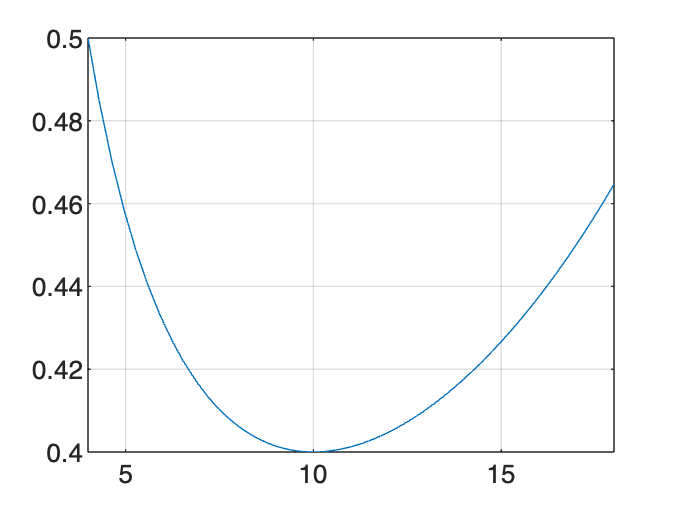

grid on

[tOpt, fObj] = newtonRaphsonMinimo(G, 10)

tOpt = 10

fObj = 0.4000

### Inciso b) Enfoque Nuevo

Gc = 0.5

Gc = 0.5000

U = @(t) Gc*interR(t)-C1*F(t)-C2*R(t)

U = function_handle with value:
    @(t)Gc*interR(t)-C1*F(t)-C2*R(t)


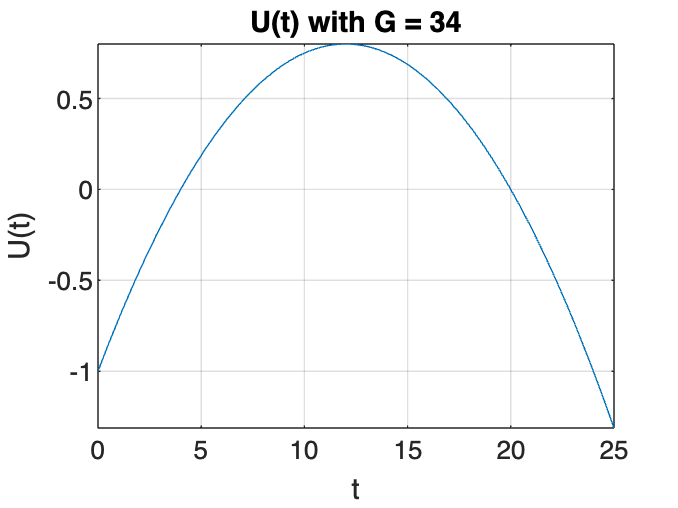

fplot(U, [a,b+5]);title("U(t) with G = 34");xlabel("t");ylabel("U(t)");grid on

[tOpt2, fObj2] = newtonRaphsonMinimo(U, 13)

tOpt2 = 12.0000

fObj2 = 0.8000

### Inciso c pt. 2: Función de utilidad con el óptimo del enfoque tradicional

U(tOpt)

ans = 0.7500

## Continuación Pregunta 3

### Inciso d)

syms t
C1 = 5;
C2 = 1;

a = 0;
b = 20;

f1 = @(t) 1/(b-a);
F1 = matlabFunction(int(f1, 0, t));

F = @(t) F1(t)*F1(t);
sym(F)

R = @(t) 1- F(t);
sym(R)

interR = matlabFunction(int(R, 0, t));
sym(interR)

f = matlabFunction(diff(F, t));
sym(f)

h = @(t) f(t)/R(t);
simplify(sym(h))


### Inciso e) Enfoque Nuevo

Gc = 0.5
U = @(t) Gc*interR(t)-C1*F(t)-C2*R(t)
fplot(U, [a,b+5]);title("U(t) with G = 548");xlabel("t");ylabel("U(t)");grid on
[tOpt2, fObj2] = newtonRaphsonMinimo(U, 13)

### Inciso f): Enfoque tradicional

G = @(t) (C1*F(t)+C2*R(t))/interR(t)
fplot(G,[4,18])
grid on
[tOpt, fObj] = newtonRaphsonMinimo(G, 9)

### Inciso f pt. 2: Función de utilidad con el óptimo del enfoque tradicional

U(tOpt)

## Problema 4

f(x): Densidad de la demanda x durante LT (tiempo de entrega del proveedor). (I <= x <= S). Ésta tiene asociada las bien conocidas E(x) y F(x). 

D: Valor esperado de la demanda en el horizonte de planeación. 

Co: Costo de poner una orden. 

Ch: Costo de mantener una unidad del producto por unidad de tiempo. 

p: Costo por no tener una unidad en inventario.

MATLAB NO FUNCIONA, es necesario aprender a utilizar la plantilla de inventarios que está en módulos canvas. 

function [x, fx, i, min] = newtonRaphsonMinimo(f,x)
    %Parámetros iniciales
    max = 52;
    tol = sqrt(eps);
    i = 0;
    cond =  true;
    %Declaramos las funciones anónimas
    f = f;
    fs = sym(f);
    dfs = diff(fs);
    dfs2 = diff(dfs);
    df = matlabFunction(dfs);
    df2 = matlabFunction(dfs2);
    if nargin(df)<1
        error('Function has not second reivate')
    end
    if nargin(df2) < 1
        df2 = @(x) df2();
    end
    while cond
        xp = x;
        x = xp-df(xp)/df2(xp);
        cond = abs((x-xp)/x) > tol && i < max;
        i = i+1;
    end
    min = df2(x) > 0;  
    fx = f(x);
end